# Determine the z-offset of a point cloud relative to a ground plane

Read the point cloud data.

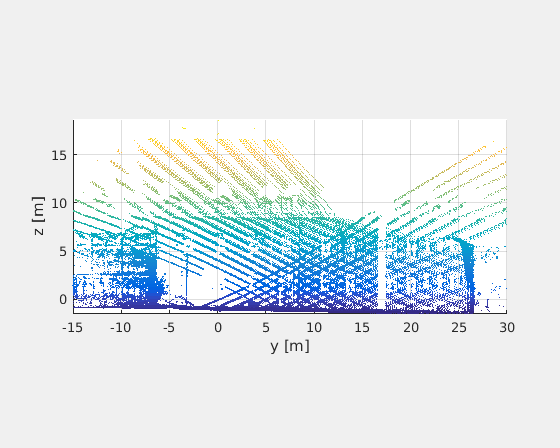

% Read the sensor point cloud.
pc = removeInvalidPoints(pcread('pcd/data/bonirob_campus.pcd'));
pc = pcdownsample(pc, 'gridAverage', 0.005);
pcshow(pc); view(90,0); ylim([-15,30]); labelaxes('m')

Compute the offset as the mean height of an elevation map generated from the point cloud.

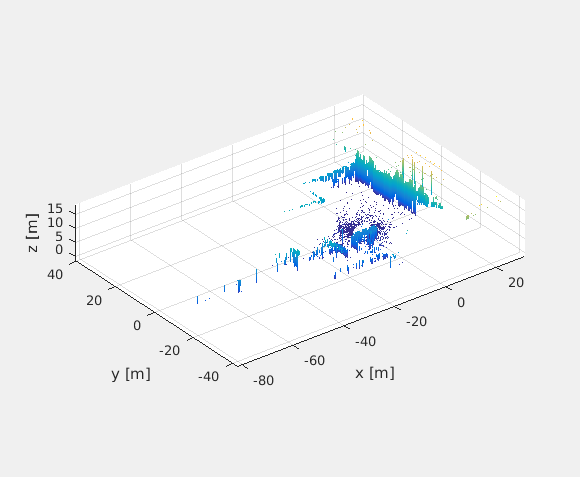

% Compute the elevation map.
em = elevationmap(pc, 0.05);
em.plot; labelaxes('m'); grid


% Compute the offset as the mean height of all map tiles.
offsetEm = mean(em.elevation(:), 'omitnan')

offsetEm = 1.1691

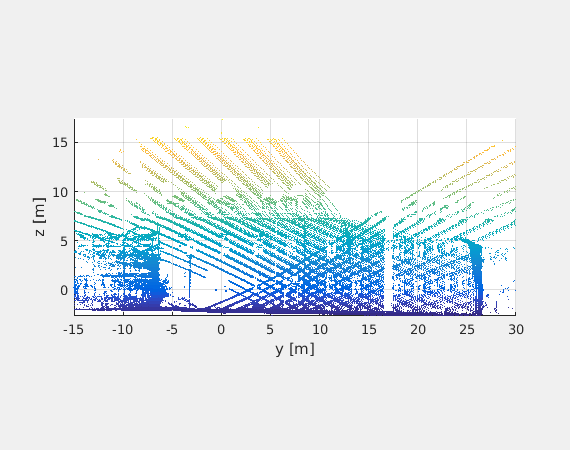


% Plot the shifted scan.
pcEm = pointCloud(pc.Location - repmat([0,0,offsetEm], pc.Count, 1));
pcshow(pcEm); view(90,0); ylim([-15,30]); labelaxes('m')

Compute the offset as the mean height of the lowest 20% of all points.

% Sort the point clouds in order of their z-coordinate.
pz = sort(pc.Location(:,3));
offsetSort = mean(pz(1:round(numel(pz)*0.2)))

offsetSort = -1.0335

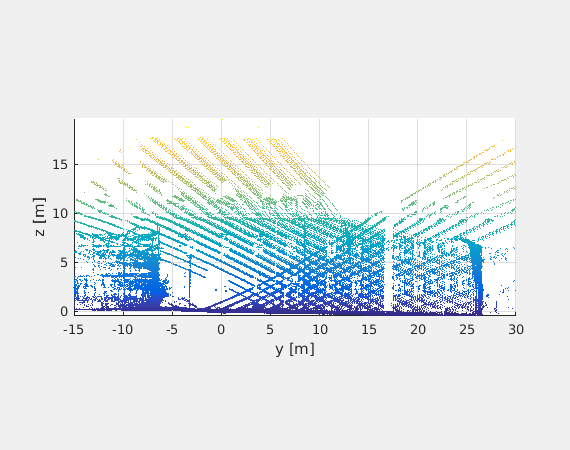


% Plot the shifted scan.
pcSort = pointCloud(pc.Location - repmat([0,0,offsetSort], pc.Count, 1));
pcshow(pcSort); view(90,0); ylim([-15,30]); labelaxes('m')